# Bioavailability Simulation of Drug Like Molecules Using Simbiology Toolbox

### Introduction

#### Background: Prepare the dataset

Building on the foundation concepts from one of our previous examples, ([Visualize and Analyze Molecular Structures](https://github.com/mathworks/Chemistry-Visualize-and-Analyze-Molecular-Structures)), we explore a practical cheminformatics workflow aimed at drug discovery. We first examined the "`LogP_LogS.csv`" dataset to identify molecules that are structurally similar to following known FDA-approved SGLT2 inhibitors (Fig.1). This dataset is generously provided by Professor Thierry Langer from the University of Vienna [1].

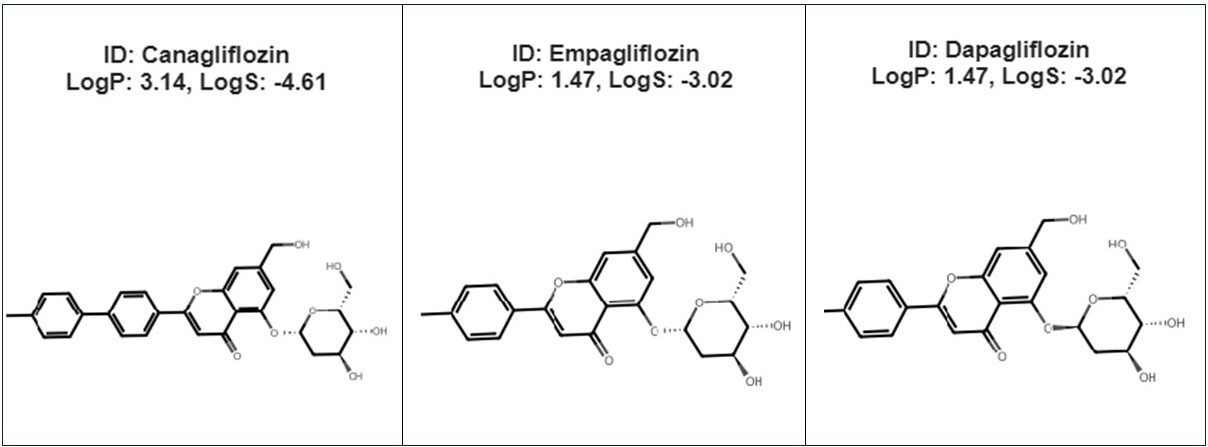

**Fig.1:** Three FDA approved SGLT2 inhibitor used as reference in this example.

By calling RDKit through Python and accelerating computations with MATLAB's GPU capabilities, the code computes molecular fingerprints and performs large-scale Tanimoto similarity analysis between candidate compounds and the above listed reference inhibitors. Molecules above a certain similarity threshold (0.3) are selected and visualized (Fig.2). 

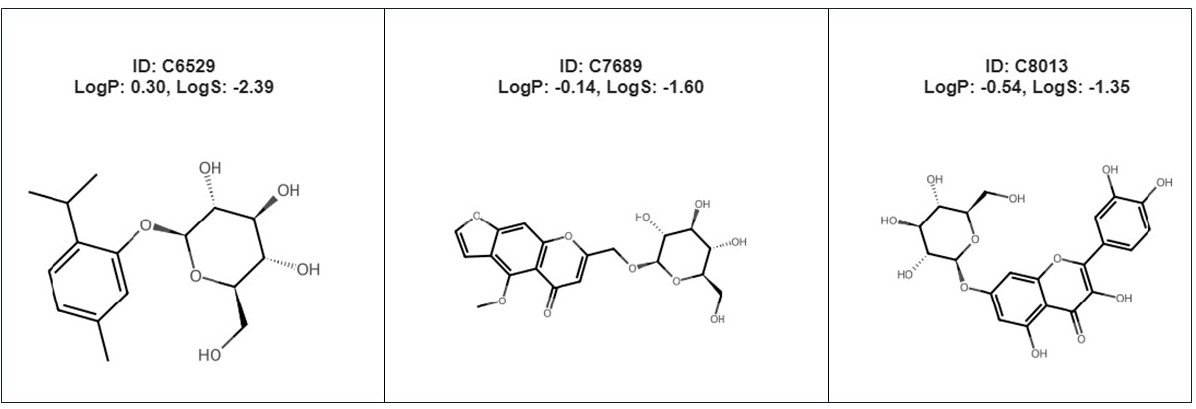

**Fig.2: **Three relatively similar molecules serving as potential candidates for SGLT2 inhibition in this example.

The above six molecules are stored in a new dataset "`SGLT2_Candidates.csv`" and will be used for the rest of this example. 

If you are interested in learning more about how the above similarity search works, visit the `"Similarity_Search"` folder in this repo, and try the code provided there. For further exploration, we also encourage you to explore our previous example on [GPU-Accelerated Molecular Clustering](https://github.com/mathworks/Chemistry-Molecular-Clustering-on-GPU).

#### Connect Cheminformatics to Pharmacokinetics Simulations

Bioavailability is the fraction of an administered drug (orally) that reaches systemic circulation in an active form. Bioavalibility is a critical determinant of a molecule's therapeutic potential and is a key consideration in early drug development.

**LogP** (lipophilicity) and **LogS** (aqueous solubility) are two major physicochemical properties that influence bioavailability. Molecules with poor solubility may fail to dissolve sufficiently in the gastrointestinal tract, while those with suboptimal lipophilicity may not permeate biological membranes effectively. For a deeper understanding of this topic, check out our earlier example on [importing, visualizing, and partitioning molecular datasets](https://github.com/mathworks/Chemistry-Import-Visualize-and-Partition-Molecular-Datasets).

In the remaining of this example, we model the early stage of oral drug absorption by simulating how LogP and LogS affect the dissolution, absorption, and distribution of a compound in a simplified pharmacokinetic system (Fig.3). The model includes compartments for solid drug in the gastrointestinal (GI) tract, dissolved drug, and the central (blood) compartment, with dissolution and absorption rates driven by solubility and a permeability function derived from LogP and molecular weight, based on a well-established correlation from Winiwarter et al. [2]. 

The modeling and simulation is done using the [Simbiology toolbox](https://www.mathworks.com/products/simbiology.html).

### Simbiology Model for Bioavalibility

This example serves as a bridge between cheminformatics-derived molecular descriptors and pharmacokinetic simulations, encouraging exploration of how molecular properties influence drug performance in vivo. We will simulate and visualize the plasma concentration profiles of the above listed molecules that are given in "`SGLT2_Candidates.csv`".

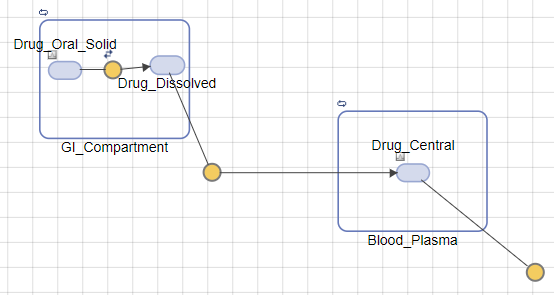

**Fig.3:** Simbiology diagram showing how the Bioavailability is modeled.

The diagram in Fig.(3) shows the pharmacokinetics of an orally administered drug using a compartmental model with solid, dissolved, and plasma phases. This is modeled by the following system of ordinary differential equations ([ODE](https://www.mathworks.com/help/symbolic/solve-a-system-of-differential-equations.html)) models the concentration changes of an oral drug:

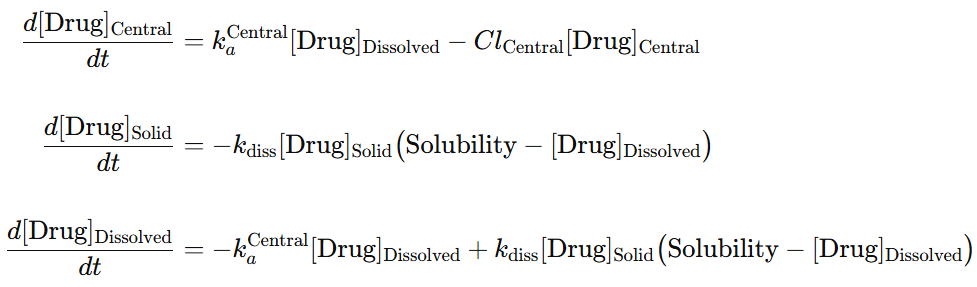

Where

 is the concentration of the drug in the central (blood plasma) compartment.

 is the concentration (or amount) of the drug in the solid form before dissolution.

is the concentration of the drug dissolved in the gastrointestinal (GI) tract.

 is the clearance rate constant representing elimination of drug from the central compartment.

is the dissolution rate constant for the solid oral drug turning into dissolved drug.

is the maximum solubility limit of the drug in the GI tract fluid 

  is the absorption rate constant from dissolved drug in GI tract into the central compartment (blood), and defined as [1]:

in which MW is molecular weight.

The Purpose of this model is to simulate how the change in LogP and LogS affects the  when different molecules in the dataset "`SGLT2_Candidates.csv`" is administrated orally. 

### Load molecular property data

Extract LogS, logP, molecular weight, and compute solubility (µg/mL).

data = readtable('SGLT2_Candidates.csv', 'VariableNamingRule', 'preserve');
numRows = height(data);
fprintf('The dataset has %d molecules.\n', numRows);

The dataset has 6 molecules.



LogS = data.logS;
DrugLogP = data.logP;
DrugMolecularWeight = data.MW;
Solubility = 10.^LogS .* DrugMolecularWeight .* 1e3;  % µg/mL
CompoundIDs = string(data.CompoundID); 

### Load and Configure SimBiology Model

We load the SimBiology project file (`Bioavailability.sbproj`) which contains the above mentioned pharmacokinetic model (Fig.3) and prepares it for simulation. This retrieves the simulation [configuration settings](https://www.mathworks.com/help/simbio/ref/simbiology.configset.html), disables unit conversion to avoid potential unit mismatches, and sets the solver to [`ode15s`](https://www.mathworks.com/help/matlab/ref/ode15s.html), which is well-suited for stiff systems commonly encountered in biological models. The simulation time is set to 12 hours. High numerical accuracy is enforced by specifying tight absolute and relative tolerances. These settings ensure stable and precise simulation of the drug's absorption and distribution over time.

s = sbioloadproject("Bioavailability.sbproj", "m1");
bioModel = s.m1;

% Configure simulation options
cset = bioModel.getconfigset;
cset.CompileOptions.UnitConversion = false;  % Avoid unit conflicts
cset.SolverType = 'ode15s';
cset.TimeUnits = 'hour';
Tend = 12; 
cset.StopTime = Tend;
cset.MaximumWallClock = 1;  % In seconds
cset.SolverOptions.AbsoluteTolerance = 1e-9;
cset.SolverOptions.RelativeTolerance = 1e-6;


### Parameterize and Simulate Bioavailability

We can now prepare the SimBiology model for efficient simulation of how drug properties affect its concentration in the body after an oral dose. We begin by setting up the dosing regimen, then build a reusable simulation function that links key input properties, like lipophilicity, solubility, and molecular weight, to the predicted drug levels in the central compartment. As shown in the following code block this is done by using `[createSimFunction](https://www.mathworks.com/help/simbio/ref/model.createsimfunction.html)` that simulates different molecular profiles based on LogP, solubility, and molecular weight.

Finally, we accelerate this function to ensure rapid execution during future simulations, making it ideal for tasks like sensitivity analysis or parameter exploration. 

% Get oral dose setup
once = getdose(bioModel, "Oral dose");
doseTable = getTable(once);

% Create and accelerate simulation function
simfun = createSimFunction(bioModel, ...
    {'DrugLogP','Solubility','DrugMolecularWeight'}, ...
    {'Drug_Central'}, ...
    once, [], ...
    'UseParallel', false, 'AutoAccelerate', false);

accelerate(simfun);

### Run simulations for all molecules

We are now ready to execute the pre-built simulation to predict how the drug behaves in the body based on its properties and dosing over the defined time period. The results are stored for further analysis.

simresults = simfun([DrugLogP, Solubility, DrugMolecularWeight], Tend, doseTable);

### Plot Plasma Drug Concentrations

Finally we create a figure to visualize the simulation results for multiple drug candidates. This is done by looping through each simulation, and plotting the plasma drug concentration over time.

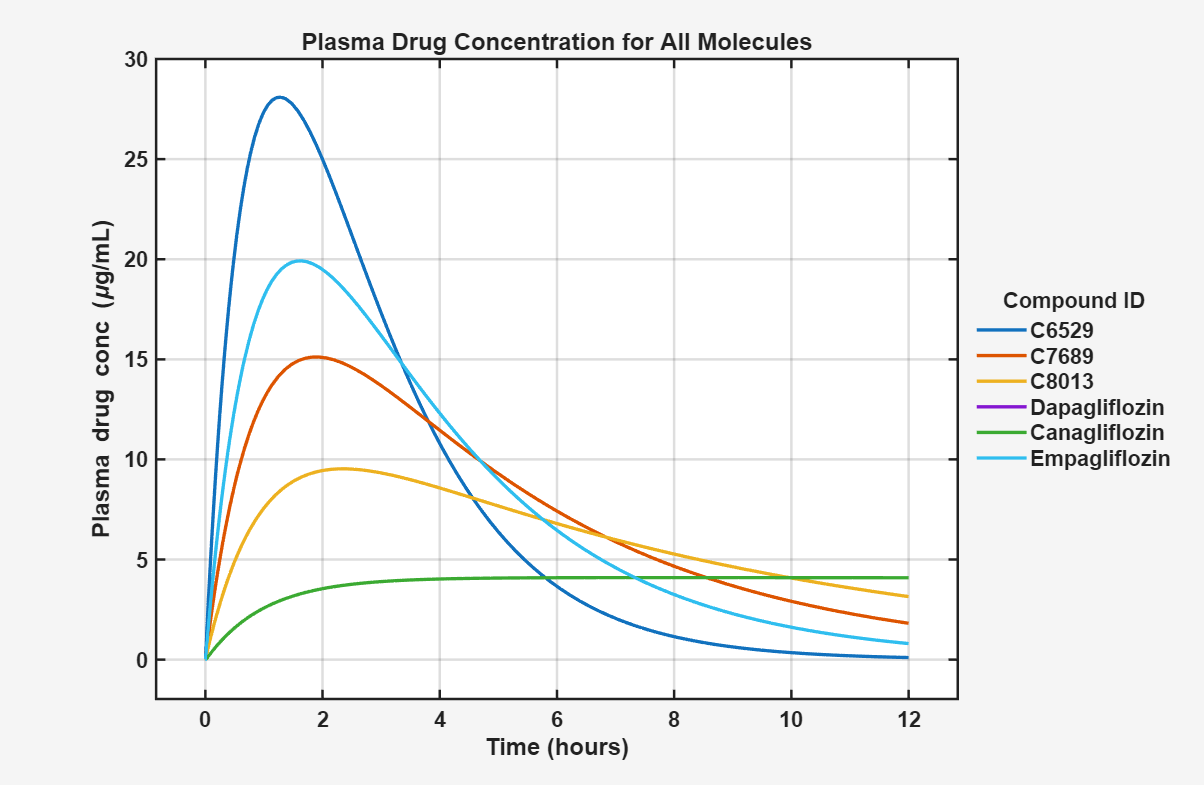

f = figure(Visible=false);
f.Position(3:4) = [962 628];
centerfig(f);
colors = colororder;

tl = tiledlayout(f, 1, 1);
ax1 = nexttile(tl); 
hold(ax1, "on"); 
grid(ax1, "on");

for jz = 1:numel(simresults)
    temp_sim = simresults(jz);
    if isempty(temp_sim)
        continue
    end
    time_hours = temp_sim.Time;
    dataNames = temp_sim.DataNames;
    drugIdx = find(strcmp(dataNames, 'Drug_Central'));

    plot(ax1, time_hours, temp_sim.Data(:, drugIdx), ...
        'LineWidth', 2, ...
        'Color', colors(mod(jz-1, size(colors,1)) + 1, :), ...
        'DisplayName', CompoundIDs(jz));
end

xlabel(ax1, 'Time (hours)', 'fontsize', 15, 'fontweight', 'bold');
ylabel(ax1, 'Plasma drug conc (\mug/mL)', 'fontsize', 15);
title(ax1, 'Plasma Drug Concentration for All Molecules');
lgd = legend(ax1, 'show');
lgd.Title.String = 'Compound ID';

set(ax1, 'fontsize', 13, 'linewidth', 1.5, 'fontweight', 'bold', ...
         'box', 'on', 'XLimitMethod', 'padded', 'YLimitMethod', 'padded');
set(lgd, 'fontsize', 13, 'location', 'eastoutside', 'box', 'off');
f.Visible = true;

### Conclusion

This example demonstrates a seamless integration of cheminformatics and pharmacokinetics, highlighting how molecular descriptors like LogP and LogS can inform early drug development decisions. By combining similarity-based candidate selection with a mechanistic SimBiology model, we simulated the absorption and distribution of potential SGLT2 inhibitors following oral administration. The resulting plasma concentration profiles provide insight into how structural and physicochemical properties influence bioavailability. This workflow not only bridges chemical structure and biological function but also showcases how MATLAB can accelerate drug discovery by connecting data-driven screening with dynamic system-level simulation.

### Exercise: How Does SGLT2 Inhibition Affect Glucose and Insulin Dynamics?

Now that you have modeled how molecular properties like LogP and LogS influence oral drug absorption, take a moment to explore how those same drug candidates might affect physiological systems downstream. Explore the following MathWorks example:

[Incorporate SGLT2 Inhibition into Physiologically Based Glucose-Insulin Model](https://www.mathworks.com/help/simbio/ug/build-sglt2-glucose-insulin-model.html)

This example walks you through building a mechanistic SimBiology model that simulates how SGLT2 inhibitors impact glucose re-absorption in the kidney, insulin secretion, and urinary glucose excretion. It's a great way to see how drug action at the molecular level translates into whole-body physiological effects.

Think about the following questions:

**(a)** How does this system-level example relate to the bioavailability model we just simulated?

**(b)** If the compounds you selected earlier have low or high absorption , how might that influence their effectiveness in this glucose–insulin model?

**(c) **What might you need to add or modify to connect both workflows, from cheminformatics-based screening to full mechanism-of-action modeling?

### References

**[1] **Oliver Wieder, et. al., "Improved Lipophilicity and Aqueous Solubility Prediction with Composite Graph Neural Networks", Molecules 2021, 26, 6185. 

**[2] **S. Winiwarter, et. al. "Correlation of human jejunal permeability (in vivo) of drugs with experimentally and theoretically derived parameters. A multivariate data analysis approach",  J. Med. Chem. 1998, 41(25):4939-49.